# Fuel Economy Analysis

This is an example of data analysis on historical fuel economy data. We have data from various cars built from year 2000 up to 2012. In this report, we will automate importing data from spreadsheets, creating customized plots, splitting data into groups, and interactively applying custom curve fits.

We can share our results using an interactive Fuel Economy App or by exporting this Live Script as documentation of our analysis.

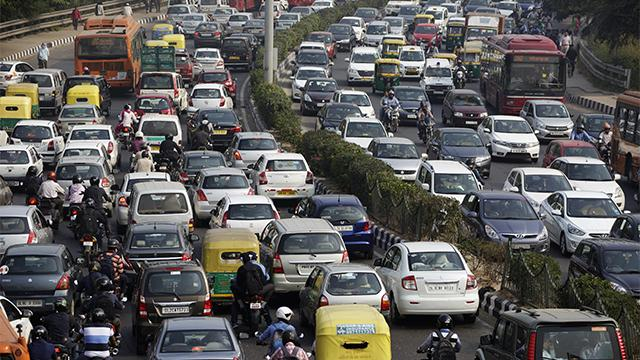

## Import Data into Table

Import the data from Excel 

data = importfile('2006dat.xlsx')

data = 2685×22 table
    Year        MfrName              CarLine           Car_Truck    EngDisp    Police    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    PRP    FuelType    City_Highway     HC       CO     CO2    MPG     Valves_Cyl    CoastDownTime
    ____    _______________    ____________________    _________    _______    ______    _______    ____________    _____    ______    ____    

## Visualize Data

Plot MPG versus Rated Horsepower

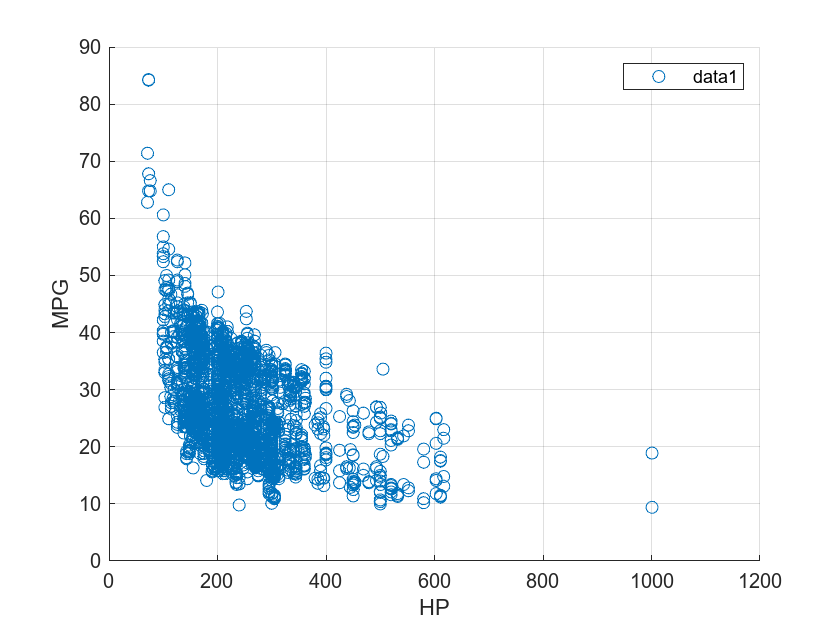

createfigure(data.RatedHP,data.MPG)

## Visualize Data in Groups

Notice there are clear "bands" of data; we may find it useful to separate these bands into distinct datasets and analyze them independently. We can easily visualized grouped data using a grouped scatter plot. Embedded Task App

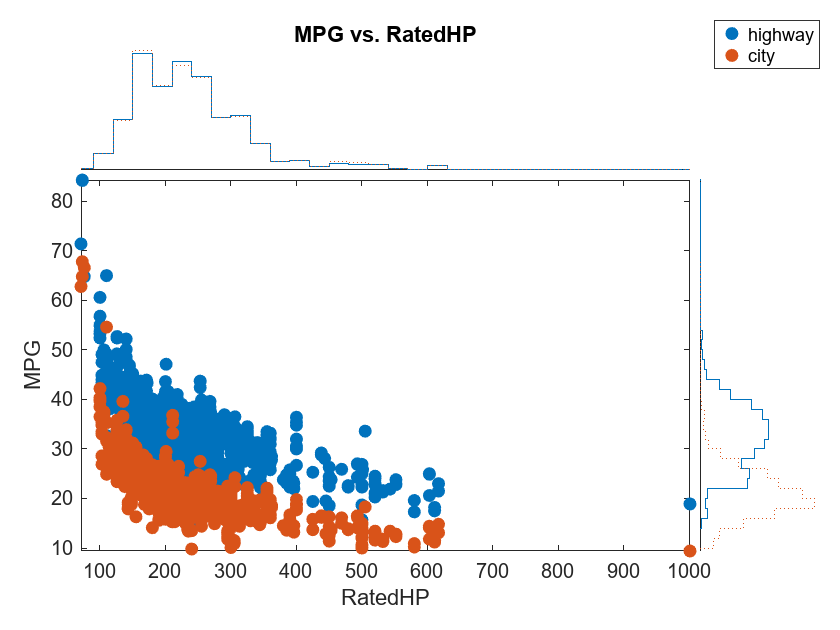

% Create scatterhistogram of data.RatedHP and data.MPG
sh3 = scatterhistogram(data.RatedHP,data.MPG,"GroupData",data.City_Highway);

% Add xlabel, ylabel, and title
xlabel("RatedHP")
ylabel("MPG")
title("MPG vs. RatedHP")

##  City Data

We now extract City Data using [logical array indexing](matlab: web(fullfile(docroot, 'matlab/matlab_prog/find-array-elements-that-meet-a-condition.html'))). 

city = data(data.City_Highway == 'city',:)

city = 1345×22 table
    Year        MfrName              CarLine           Car_Truck    EngDisp    Police    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    PRP    FuelType    City_Highway     HC       CO     CO2    MPG     Valves_Cyl    CoastDownTime
    ____    _______________    ____________________    _________    _______    ______    _______    ____________    _____    ______    ____    

## Model City Data

We can consider fitting a standard curve (polynomial, power, etc.) to our dataset, but in this case, we already know the general form of the variable relationships. 


$$\textrm{MPG}=b_1 +\frac{b_2 }{\textrm{RatedHP}}$$


We can use this equation to fit a custom curve to our data using the [Curve Fitting Tool](matlab: cftool). 

model =      General model:
     model(x) = a+b/x
     Coefficients (with 95% confidence bounds):
       a =       8.568  (8.025, 9.111)
       b =        2657  (2549, 2765)

model = createFit(city.RatedHP,city.MPG)

## Predict MPG from Rated HP

model(170)

ans = 24.1965